# Preprocessing Data

whalesRaw = importWhaleData("BlueWhaleData.csv")

whalesRaw = 16249x8 table
    individual_local_identifier           timestamp           longitude    latitude    sensorQuality    sensorMeasurements    sensor_type    manually_marked_outlier
    ___________________________    _______________________    _________    ________    _____________    __________________    ___________    _______________________

         1993CA-Bmu-00834          1993-08-29 01:13:00.000     -122.43      37.058      <undefined>            NaN                gps                  ""           
         1993CA-Bmu-10823          1993-08-28 18:20:00.000     -122.41      37.012      <undefined>            NaN                gps                  ""           
         1993CA-Bmu-10833          1993-0

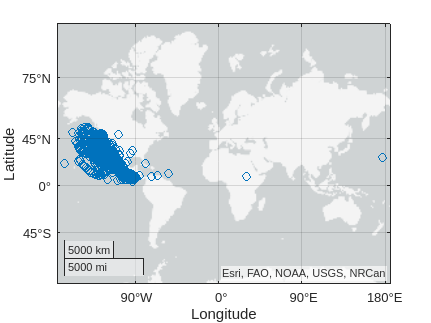


geoscatter(whalesRaw.latitude, whalesRaw.longitude)

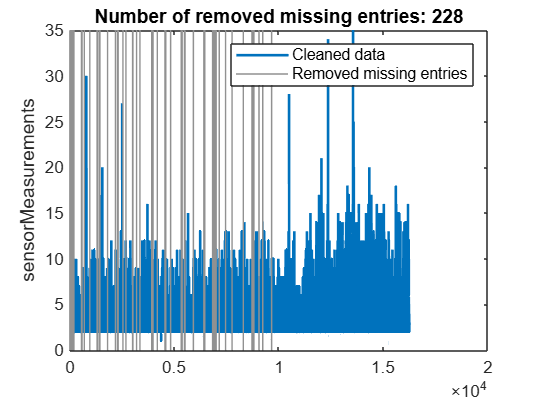

% Remove missing data
[whalesClean1,missingIndices] = rmmissing(whalesRaw, ...
    "DataVariables","sensorMeasurements");

% Display results
figure

% Plot cleaned data
plot(find(~missingIndices),whalesClean1.sensorMeasurements,"SeriesIndex",1, ...
    "LineWidth",1.5,"DisplayName","Cleaned data")
hold on

% Plot removed missing entries
x = repelem(find(missingIndices),3);
y = repmat([ylim(gca) missing]',nnz(missingIndices),1);
plot(x,y,"Color",[145 145 145]/255,"DisplayName","Removed missing entries")
title("Number of removed missing entries: " + nnz(missingIndices))

hold off
legend
ylabel("sensorMeasurements")

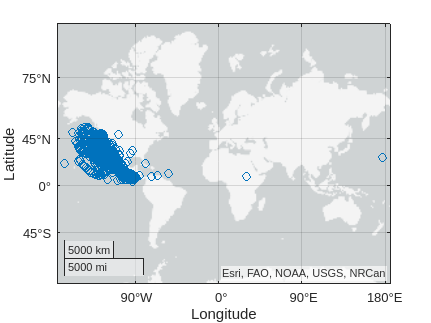

clear x y

geoscatter(whalesClean1.latitude, whalesClean1.longitude)

rowsToKeep = whalesClean1.sensorQuality ~= "Z";
whalesClean2 = whalesClean1(rowsToKeep,:)

whalesClean2 = 14830x8 table
    individual_local_identifier           timestamp           longitude    latitude    sensorQuality    sensorMeasurements        sensor_type        manually_marked_outlier
    ___________________________    _______________________    _________    ________    _____________    __________________    ___________________    _______________________

         1993CA-Bmu-00834          1993-08-29 01:23:17.000     -122.41      36.981           1                  4             argos-doppler-shift            ""             
         1993CA-Bmu-00834          1993-08-31 13:04:34.000     -122.79      37.637           B                  2             argos-doppler-shift            ""             
      

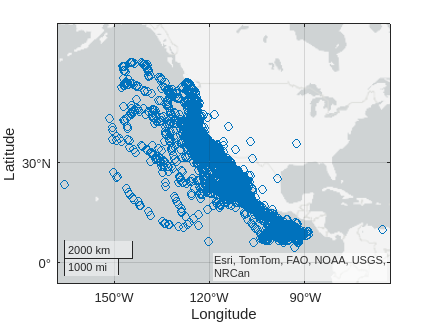


geoscatter(whalesClean2.latitude, whalesClean2.longitude)

rowsToKeep = whalesClean2.manually_marked_outlier ~= "true";
whalesClean3 = whalesClean2(rowsToKeep,:)

whalesClean3 = 14514x8 table
    individual_local_identifier           timestamp           longitude    latitude    sensorQuality    sensorMeasurements        sensor_type        manually_marked_outlier
    ___________________________    _______________________    _________    ________    _____________    __________________    ___________________    _______________________

         1993CA-Bmu-00834          1993-08-29 01:23:17.000     -122.41      36.981           1                  4             argos-doppler-shift              ""           
         1993CA-Bmu-00834          1993-08-31 13:04:34.000     -122.79      37.637           B                  2             argos-doppler-shift              ""           
      

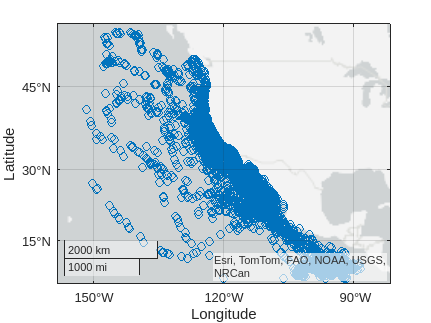


geoscatter(whalesClean3.latitude, whalesClean3.longitude)

whales = whalesClean3

whales = 14514x8 table
    individual_local_identifier           timestamp           longitude    latitude    sensorQuality    sensorMeasurements        sensor_type        manually_marked_outlier
    ___________________________    _______________________    _________    ________    _____________    __________________    ___________________    _______________________

         1993CA-Bmu-00834          1993-08-29 01:23:17.000     -122.41      36.981           1                  4             argos-doppler-shift              ""           
         1993CA-Bmu-00834          1993-08-31 13:04:34.000     -122.79      37.637           B                  2             argos-doppler-shift              ""           
         199

save cleanWhaleData whales